# Testing all RTB functions

Read section 2.4 of Peter Corke Book

**Skip 'Twist'  which we will not use in this course**

## **RTB functions. Summary tables**

### **2D**

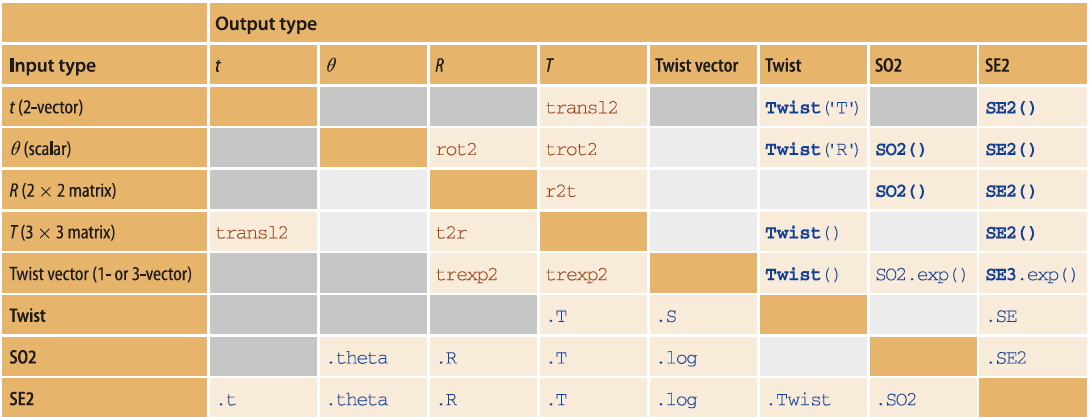

### 3D

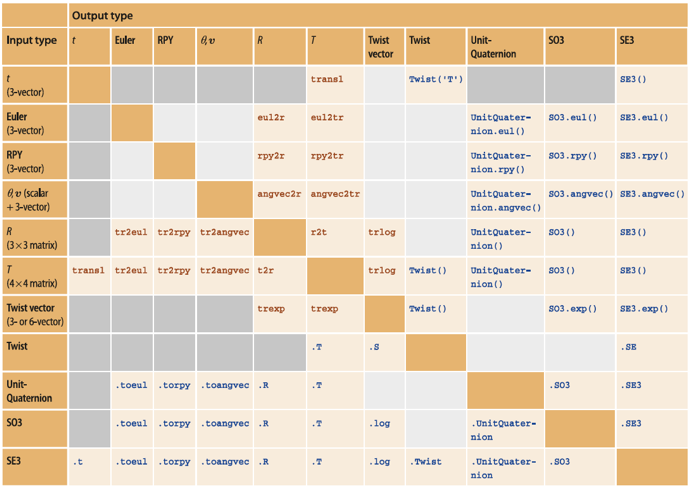

## RTB equivalence for Matrix(Classic) / Class-Object (New)

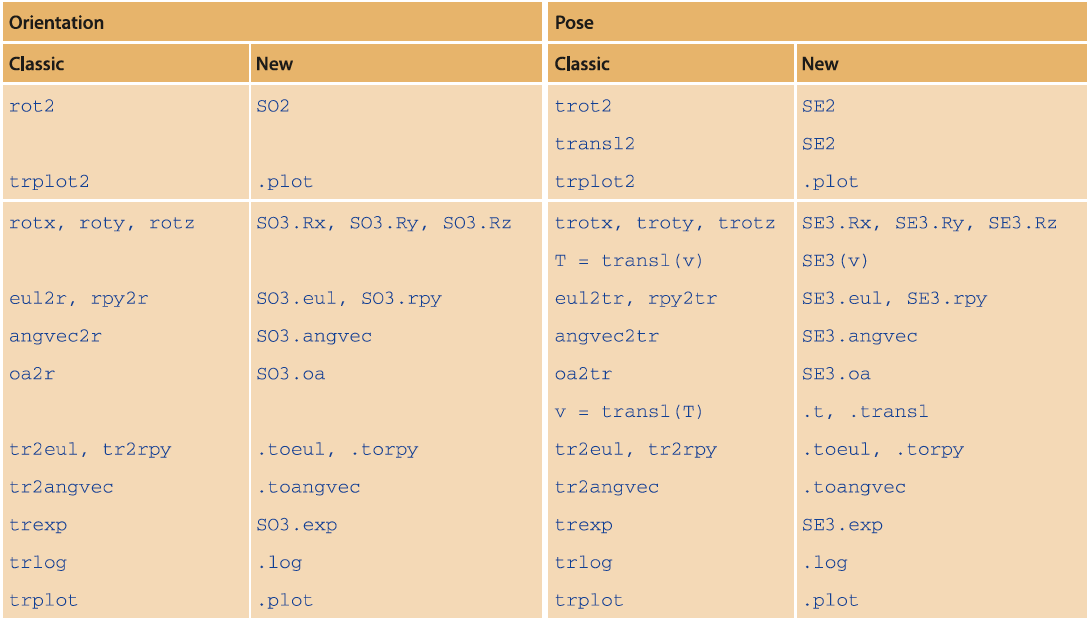

From here on we will use a mixture of classic functions and the newer classes.

clear
close all

## Input a vector

p=[1,2,3]'

### Get T 

T=transl(p)

### Get a SE3

P=SE3(p) % P is a object
P1=[P.t] % P1 recover the point as a vector
P11=P.t

p=[1 2 3;4 5 6; 7 8 9] 
P=SE3(p) % is a 4x4. Note the row(1) -> x's; row(2) -> y's; row(3) -> z's ...
ps=[P.t]
p=transl(P)

## Input Euler Angles 

zyz=[0.1 0.2 0.3]

zyz =     0.1000    0.2000    0.3000


zyzs=[0.1 0.2 0.3;0.4 0.5 0.6;0.7 0.8 0.9; 0.5 0.6 0.8; 0.7 0.9 1]

zyzs =     0.1000    0.2000    0.3000
    0.4000    0.5000    0.6000
    0.7000    0.8000    0.9000
    0.5000    0.6000    0.8000
    0.7000    0.9000    1.0000


### Get R

R=rotz(zyz(1))*roty(zyz(2))*rotz(zyz(3))

R =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


R1=eul2r(zyz)

R1 =     0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


R2=eul2r(zyzs)

R2 = R2(:,:,1) =

    0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


R2(:,:,2) =

    0.4472   -0.7778    0.4416
    0.8021    0.5672    0.1867
   -0.3957    0.2707    0.8776


R2(:,:,3) =

   -0.1734   -0.8179    0.5487
    0.8781    0.1239    0.4621
   -0.4459    0.5619    0.6967


R2(:,:,4) =

    0.1607   -0.8536    0.4955
    0.9052    0.3276    0.2707
   -0.3934    0.4050    0.8253


R2(:,:,5) =

   -0.2852   -0.7481    0.5991
    0.8600    0.0763    0.5046
   -0.4232    0.6591    0.6216


### Get T

R3=eul2tr(zyz)

R3 =     0.9021   -0.3836    0.1977         0
    0.3875    0.9216    0.0198         0
   -0.1898    0.0587    0.9801         0
         0         0         0    1.0000


R4=eul2tr(zyzs)

R4 = R4(:,:,1) =

    0.9021   -0.3836    0.1977         0
    0.3875    0.9216    0.0198         0
   -0.1898    0.0587    0.9801         0
         0         0         0    1.0000


R4(:,:,2) =

    0.4472   -0.7778    0.4416         0
    0.8021    0.5672    0.1867         0
   -0.3957    0.2707    0.8776         0
         0         0         0    1.0000


R4(:,:,3) =

   -0.1734   -0.8179    0.5487         0
    0.8781    0.1239    0.4621         0
   -0.4459    0.5619    0.6967         0
         0         0         0    1.0000


R4(:,:,4) =

    0.1607   -0.8536    0.4955         0
    0.9052    0.3276    0.2707         0
   -0.3934    0.4050    0.8253         0
         0         0         0    1.0000


R4(:,:,5) =

   -0.2852   -0.7481    0.5991         0
    0.8600    0.0763    0.5046         0
   -0.4232    0.6591    0.6216         0
         0         0         0    1.0000


### Get a Quaternion

Q=UnitQuaternion.eul(zyz)

 
Q = 
 
0.97517 < 0.0099667, 0.099335, 0.19768 >
 


Q.v

ans =     0.0100    0.0993    0.1977


Q.s

ans = 0.9752

### Get a SO3

T=SO3.eul(zyz)

 

T = 
    0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801


T=SO3.eul(zyzs)

 

T(1) = 
    0.9021   -0.3836    0.1977
    0.3875    0.9216    0.0198
   -0.1898    0.0587    0.9801

T(2) = 
    0.4472   -0.7778    0.4416
    0.8021    0.5672    0.1867
   -0.3957    0.2707    0.8776

T(3) = 
   -0.1734   -0.8179    0.5487
    0.8781    0.1239    0.4621
   -0.4459    0.5619    0.6967

T(4) = 
    0.1607   -0.8536    0.4955
    0.9052    0.3276    0.2707
   -0.3934    0.4050    0.8253

T(5) = 
   -0.2852   -0.7481    0.5991
    0.8600    0.0763    0.5046
   -0.4232    0.6591    0.6216


### Get a SE3

T=SE3.eul(zyz)
T=SE3.eul(zyzs)

## Input RPY

The same as for Euler angles apply for RPY

## Input R

### Get Euler

euler = tr2eul(R1)

### Get RPY

rpy = tr2rpy(R3)

Get Angles

angvec = tr2angvec(R3)

Get T

T = r2t(R3)

Get Twist Vector

twist = trlog(R3)

Get Unit Quaternion

uq = UnitQuaternion(R3)

Get SO3

so3 = SO3(R3)

GetSE3

se3 = SE3(R3)

## Having RPY

Get R

R = rpy2r(rpy)

Get T

R = rpy2tr(rpy)

Get Unit Quaternion

uq = UnitQuaternion.rpy(rpy)

Get SO3

so3 = SO3.rpy(rpy)

Get SE3

se3 = SE3.rpy(rpy)

## Having AngVec

Get R

R = angvec2r(angvec, zyz)

Get T

T = angvec2tr(angvec, zyz)

Get Unit Quaternion 

uq = UnitQuaternion.angvec(angvec, zyz)

Get SO3

so3 = SO3.angvec(angvec, zyz)

Get SE3

se3 = SE3.angvec(angvec, zyz)

## Having T

Get t

t = transl(T)

Get Euler

euler = tr2eul(T)

Get RPY

rpy = tr2rpy(T)

Get AngVec

angvec = tr2angvec(T)

Get R

R = t2r(T)

Get Twist Vector

twist = trlog(T)

Get Unit Quaternion

uq = UnitQuaternion(T)

Get SO3

so3 = SO3(T)

Get SE3

se3 = SE3(T)

## Having Twist Vector

Get R

R = trexp(twist)

Get T

T = trexp(twist)

Get SO3

so3 = SO3.exp(twist)

Get SE3

se3 = SE3.exp(twist)

## Having Unit Quaternion

Get Euler

euler = uq.toeul

Get RPY

rpy = uq.torpy

Get AngVec

angvec = uq.toangvec

Get R

R = uq.R

Get T

T = uq.T

Get SO3

so3 = uq.SO3

Get SE3

se3 = uq.SE3

## Having SO3

Get Euler

euler = so3.toeul

Get RPY

rpy = so3.torpy

Get AngVec

angvec = so3.toangvec

Get R

R = so3.R

Get T

T = so3.T

Get Twist Vector

twist = so3.log

Get Unit Quaternion

uq = so3.UnitQuaternion

Get SE3

se3 = so3.SE3

## Having SE3

Get t

t = se3.t

Get Euler

euler = se3.toeul

Get RPY

rpy = se3.torpy

Get AngVec

angvec = se3.toangvec

Get R

R = se3.R

Get T

T = se3.T

Get Twist vector

twist = se3.log

Get Unit Quaternion

uq = se3.UnitQuaternion

Get SO3

so3 = se3.SO3